load 3UAV_6users/PartCMin.mat

A_init = sol.A;
Q_init = sol2.Q;
P_init = sol3.P;

A = optimvar('A', K,M,N, 'Type', 'continuous', 'LowerBound', 0, "UpperBound", 1);
Q = optimvar('Q', M,2,N, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 2000);
P = optimvar('P', M, N, 'Type', 'continuous', 'LowerBound', 0, "UpperBound",Pmax);


[f, A_sum_k, A_sum_m] = fcn2optimexpr(@UserScheduling, A, P_init, Q_init, K, M, N, Rho0, H, W, NoisePower);
problem = optimproblem('ObjectiveSense', 'max');
problem.Objective = f;


problem.Constraints.cons1 = A_sum_k <= 1;
problem.Constraints.cons2 = A_sum_m <= 1;


x0.A = A_init;

global history;
history.x = [];
history.fval = [];
global stopping;
stopping.x = [];
stopping.fval = [];

show(problem)


  OptimizationProblem : 

	Solve for:
       A

	maximize :
       [argout,~,~] = UserScheduling(A, extraParams{1}, extraParams{2}, 6, 3, 150, 1e-06, 100, extraParams{3}, 1e-14)

       


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0    2701   -2.068516e+00    0.000e+00    6.239e-04


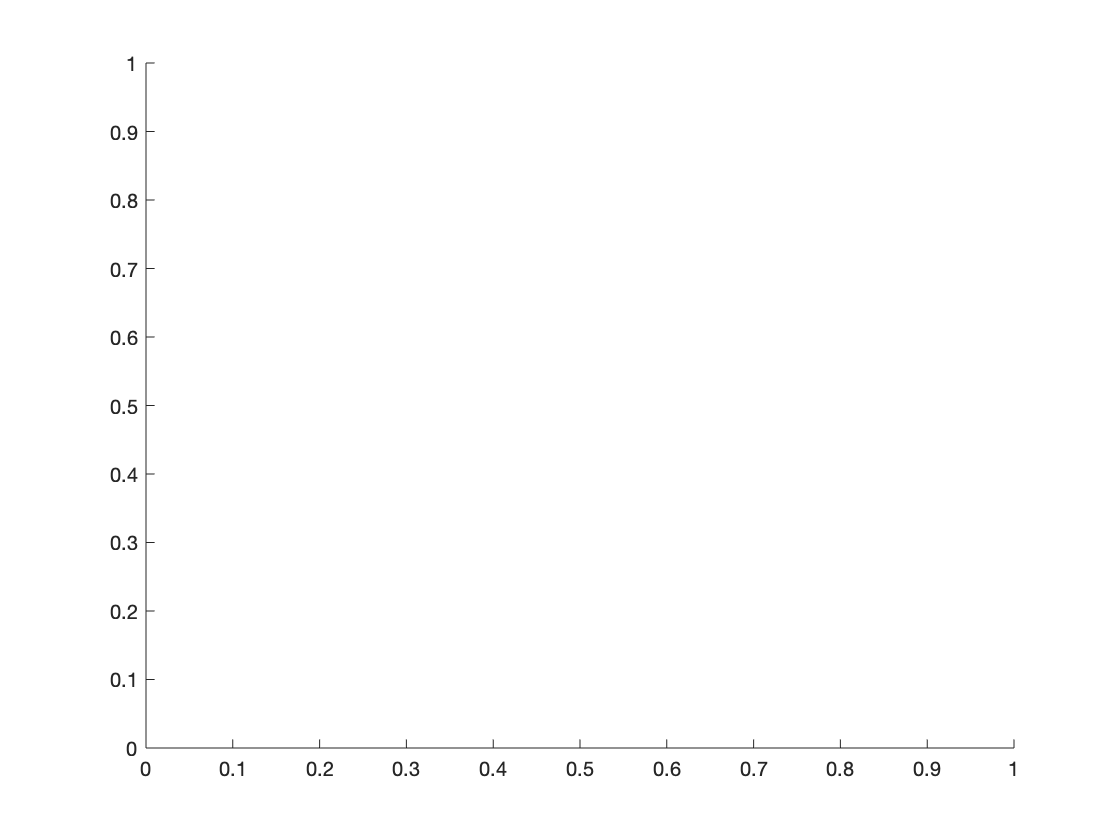

    1    5402   -1.797525e+00    6.240e-02    7.621e-04    4.123e+00
    2    8103   -1.226444e+00    0.000e+00    1.299e-03    5.768e+00
    3   10804   -5.135420e-01    0.000e+00    2.845e-03    7.922e+00
    4   13505   -3.588960e-01    0.000e+00    3.932e-03    2.531e+00
    5   16206   -4.481539e-01    0.000e+00    3.482e-03    1.216e+00
    6   18907   -4.462007e-01    0.000e+00    3.506e-03    3.892e-02
    7   21608   -4.546305e-01    0.000e+00    8.943e-04    8.091e-02
    8   24309   -8.274569e-01    0.000e+00    8.880e-04    3.673e+00
    9   27010   -1.225665e+00    0.000e+00    9.088e-04    3.922e+00
   10   29711   -1.489641e+00    0.000e+00    1.136e-03    2.664e+00
   11   32412   -1.565001e+00    0.000e+00    1.235e-03    8.751e-01
   12   35113   -1.587643e+00    0.000e+00    1.288e-03    4.280e-01
   13   37814   -1.606833e+00    0.000e+00    1.319e-03    3.365e-01
   14   40515   -1.629394e+00    0.000e+00    1.344e-03    3.831e-01
   15   43216   -1.639450e+00    0

options = optimoptions('fmincon', 'OutputFcn',@outfun, 'Display', 'iter', 'MaxFunctionEvaluations', 250000, 'OptimalityTolerance', 1.0000e-04, 'Algorithm','interior-point');
[sol, fval, exitflag, output] = solve(problem, x0, 'Options', options);

A_init = sol.A;

global history;
history.x = [];
history.fval = [];
global stopping;
stopping.x = [];
stopping.fval = [];

[f2, speed_constraint, initial_final, inter_uav_distance] = fcn2optimexpr(@TrajectoryOptimization,A_init, P_init, Q, K, M, N, Rho0, H, W, NoisePower, d_min);


problem2 = optimproblem('ObjectiveSense', 'max');
problem2.Objective = f2;


options = optimoptions('fmincon', 'OutputFcn',@outfun, 'Display', 'iter', 'MaxFunctionEvaluations', 100000, 'OptimalityTolerance', 1.0000e-06);

deltaT = T/N;
Max_Dist = deltaT * Vmax

Max_Dist = 70

problem2.Constraints.speed = speed_constraint <= Max_Dist;
problem2.Constraints.repeat = initial_final <= 200;
problem2.Constraints.inter_uav_distance = inter_uav_distance == 1;

x1.Q = Q_init;



Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     901   -2.149293e+00    0.000e+00    1.340e-05


    1    1802   -2.149293e+00    0.000e+00    1.340e-05    2.328e-04
    2    2703   -2.149294e+00    0.000e+00    1.340e-05    1.165e-03
    3    3604   -2.149294e+00    0.000e+00    1.340e-05    5.825e-03
    4    4505   -2.149297e+00    0.000e+00    1.340e-05    1.857e-02
    5    5406   -2.149307e+00    0.000e+00    1.340e-05    7.985e-02
    6    6307   -2.149358e+00    0.000e+00    1.340e-05    3.992e-01
    7    7208   -2.149612e+00    0.000e+00    1.340e-05    1.995e+00
    8    8109   -2.150871e+00    0.000e+00    1.340e-05    9.946e+00
    9    9010   -2.156824e+00    0.000e+00    1.342e-05    4.903e+01
   10    9911   -2.178417e+00    0.000e+00    1.333e-05    2.278e+02
   11   10812   -2.188573e+00    1.188e-01    1.298e-05    2.049e+02
   12   11713   -2.188601e+00    2.679e-01    1.298e-05    1.019e+00
   13   12614   -2.188538e+00    0.000e+00    1.299e-05    2.281e+00
   14   13515   -2.188548e+00    0.000e+00    1.298e-05    3.818e-01
   15   14416   -2.188549e+00    0

[sol2, fval2, exitflag2, output2] = solve(problem2, x1, 'Options', options);

Q_init = sol2.Q;

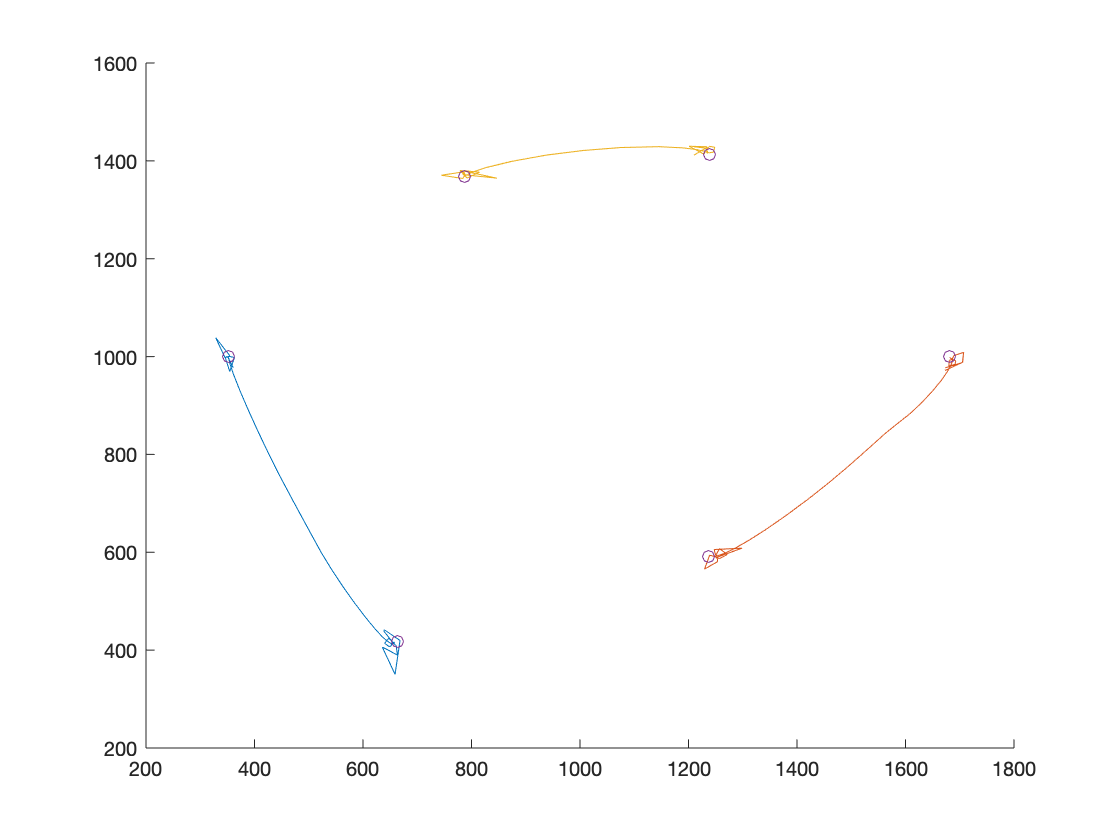

Q2 = sol2.Q;
Xs = Q2(:, 1, :);
Ys = Q2(:, 2, :);
Xs = reshape(Xs,[M,N]);
Ys = reshape(Ys, [M,N]);
for i = 1:M
    hold on
    plot(Xs(i,:), Ys(i,:));
end
scatter(W(:,1), W(:,2));
hold off

clf

global history;
history.x = [];
history.fval = [];
global stopping;
stopping.x = [];
stopping.fval = [];

[f3, power_constraint] = fcn2optimexpr(@PowerOptimization,A_init, P, Q_init, K, M, N, Rho0, H, W, NoisePower, d_min)

f3 =   Nonlinear OptimizationExpression

    [argout,~] = PowerOptimization(extraParams{1}, P, extraParams{2}, 6, 3, 150, 1e-06, 100, extraParams{3}, 1e-14, 100)

  

power_constraint =   3×150 Nonlinear OptimizationExpression array with properties:

    IndexNames: {{}  {}}
     Variables: [1×1 struct] containing 1 OptimizationVariable

  See expression formulation with show.


problem3 = optimproblem('ObjectiveSense', 'max');
problem3.Objective = f3;

options = optimoptions('fmincon', 'OutputFcn',@outfun, 'Display', 'iter', 'MaxFunctionEvaluations', 100000, 'OptimalityTolerance', 1.0000e-06, "Algorithm","interior-point", "StepTolerance",0);

problem3.Constraints.power_constraint = power_constraint <= Pmax;

x2.P = P_init;


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     451   -2.017791e+00    0.000e+00    7.775e-02


    1     902   -2.046656e+00    0.000e+00    4.964e-01    6.894e-02
    2    1355   -2.047141e+00    0.000e+00    4.950e-01    1.523e-02
    3    1807   -2.046431e+00    0.000e+00    4.510e-02    1.394e-02
    4    2258   -2.065393e+00    0.000e+00    4.521e-02    2.446e-02
    5    2718   -2.068222e+00    0.000e+00    2.340e-01    1.517e-03
    6    3169   -2.077818e+00    0.000e+00    1.992e-01    4.659e-02
    7    3622   -2.079791e+00    0.000e+00    4.132e-01    1.238e-02
    8    4073   -2.086248e+00    0.000e+00    3.193e-01    2.938e-02
    9    4527   -2.086772e+00    0.000e+00    1.975e-01    6.468e-03
   10    4978   -2.087844e+00    0.000e+00    1.996e-01    9.573e-03
   11    5431   -2.088375e+00    0.000e+00    3.253e-01    5.556e-03
   12    5885   -2.088596e+00    0.000e+00    4.139e-01    1.380e-03
   13    6338   -2.088637e+00    0.000e+00    2.012e-01    4.299e-03
   14    6789   -2.089071e+00    0.000e+00    2.061e-01    4.527e-03
   15    7243   -2.089068e+00    0

[sol3, fval3, exitflag3, output3] = solve(problem3, x2, 'Options', options);